% Load the scope data from the workspace
out = load("roopecgdyoeraw.mat")

out = struct with fields:
    out: [1×1 Simulink.SimulationOutput]


out = out.out

out =   Simulink.SimulationOutput:

                 simout: [15100x1 double] 
                   tout: [151x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


max(out.tout)

ans = 10

t = linspace(0,max(out.tout),15100)

t =          0    0.0007    0.0013    0.0020    0.0026    0.0033    0.0040    0.0046    0.0053    0.0060    0.0066    0.0073    0.0079    0.0086    0.0093    0.0099    0.0106    0.0113    0.0119    0.0126    0.0132    0.0139    0.0146    0.0152    0.0159    0.0166    0.0172    0.0179    0.0185    0.0192    0.0199    0.0205    0.0212    0.0219    0.0225    0.0232    0.0238    0.0245    0.0252    0.0258    0.0265    0.0272    0.0278    0.0285    0.0291    0.0298    0.0305    0.0311    0.0318    0.0325


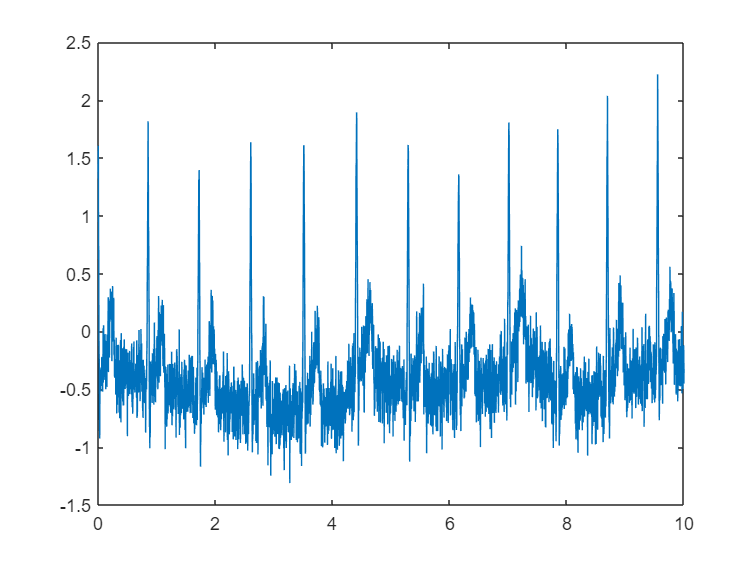

plot(t, out.simout)

length(out.simout)

ans = 15100



% Detect the R-peaks using the "findpeaks" function
[~, locs_Rwave] = findpeaks(out.simout,t, 'MinPeakHeight', 1, 'MinPeakDistance', 0.3)

locs_Rwave =     0.0033    0.8530    1.7246    2.6055    3.5108    4.4129    5.2911    6.1547    7.0117    7.8449    8.6940    9.5496


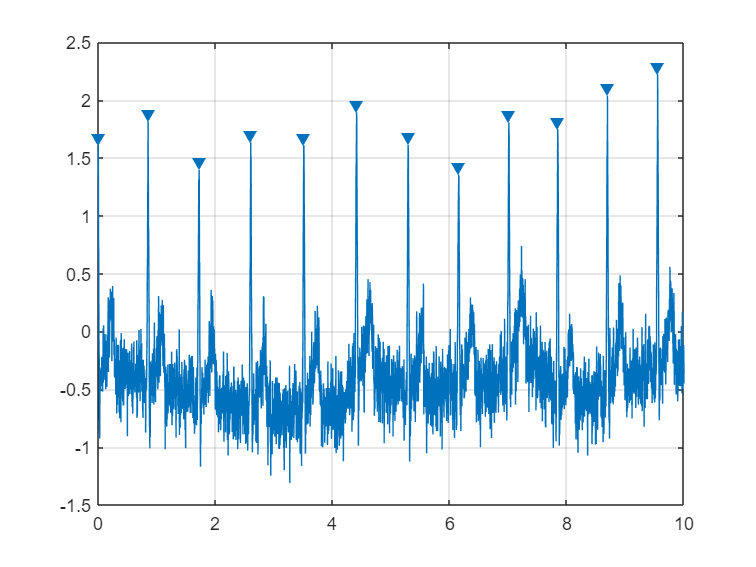

findpeaks(out.simout,t, 'MinPeakHeight', 1, 'MinPeakDistance', 0.3)

locs_Rwave

locs_Rwave =     0.0033    0.8530    1.7246    2.6055    3.5108    4.4129    5.2911    6.1547    7.0117    7.8449    8.6940    9.5496



HR = length(locs_Rwave) * 6; % Heart rate (bpm)

fprintf('Heart rate: %0.2f bpm\n', mean(HR));

Heart rate: 72.00 bpm


[~, snr_value] = snr(out.simout);
snr_value = abs(snr_value)

snr_value = 10.6227

% Application of Filters for Pre-Processing - Derived From Literature [2]
object = load("roopecgdyoeraw.mat")

object = struct with fields:
    out: [1×1 Simulink.SimulationOutput]


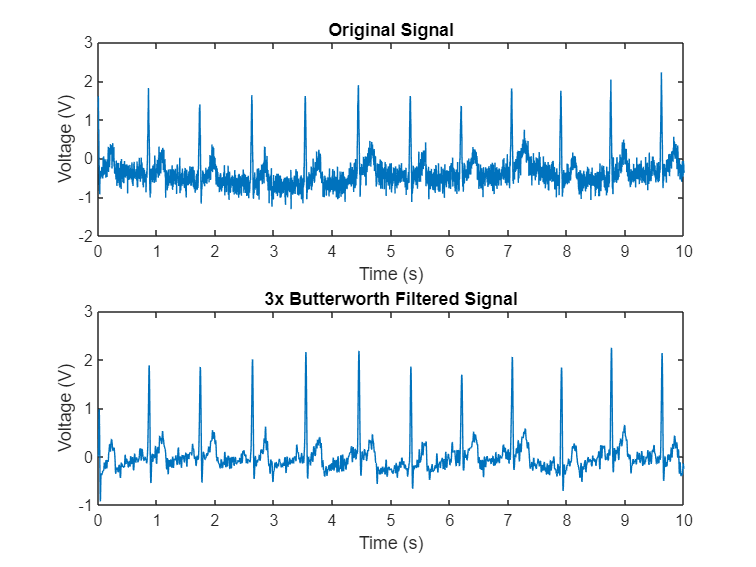

output = object.out.simout;
t = linspace(0,max(object.out.tout),length(object.out.tout));

fs = 1500; % sampling rate
fhp = 0.2; % high-pass cutoff frequency
flp = 40; % low-pass cutoff frequency
f0 = 50; % notch filter frequency
bw = 4; % notch filter bandwidth

% Butterworth filter designs
[bhp, ahp] = butter(4, fhp/(fs/2), 'high'); %Highpass
[blp, alp] = butter(4, flp/(fs/2), 'low'); % Lowpass Filter
[bnotch, anotch] = butter(4, [(f0-bw/2)/(fs/2), (f0+bw/2)/(fs/2)], 'stop'); % Notch Filter

% apply hp, lp, notch in order
x_hp = filter(bhp, ahp, output); % high-pass filter
x_lp = filter(blp, alp, x_hp); % low-pass filter
x_notch = filter(bnotch, anotch, x_lp); % notch filter


figure;
t = (1:length(output))/fs; % time axis
subplot(2,1,1);
plot(t, output);
title('Original Signal');
xlabel('Time (s)');
ylabel('Voltage (V)');
xlim([0 10]);

subplot(2,1,2);
plot(t, x_notch);
title('3x Butterworth Filtered Signal');
xlabel('Time (s)');
ylabel('Voltage (V)');
xlim([0 10]);

[~, snr_value] = snr(x_notch);
snr_value = abs(snr_value)

snr_value = 10.9043

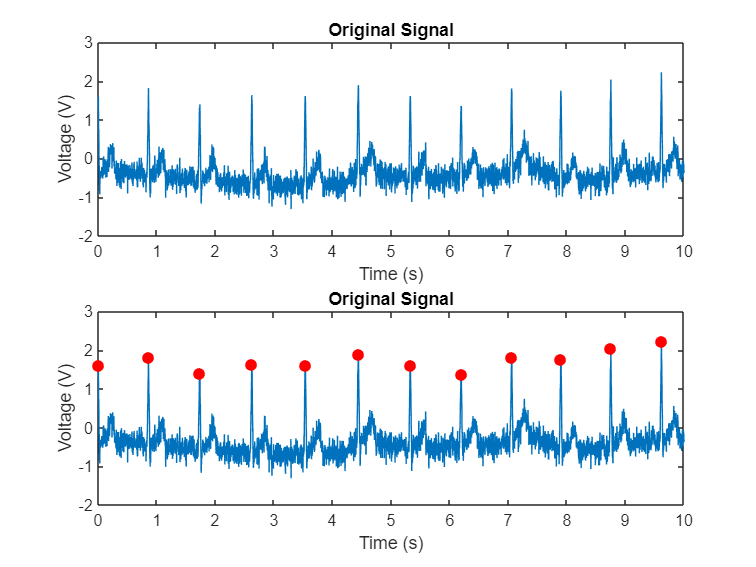

fs = 1500;
t = (1:length(out.simout))/fs;

% Detect R-peaks in the ECG signal
[peaks,locs] = findpeaks(out.simout,'MinPeakDistance',0.3*fs,'MinPeakHeight',1);

% Plot the ECG signal with markings on the R-peaks
plot(t,out.simout, Color=[0 0.4470 0.7410]);
hold on;
plot(t(locs),peaks,'ro','MarkerFaceColor','r');
hold off;

title('Original Signal');
xlabel('Time (s)');
ylabel('Voltage (V)');
xlim([0 10]);

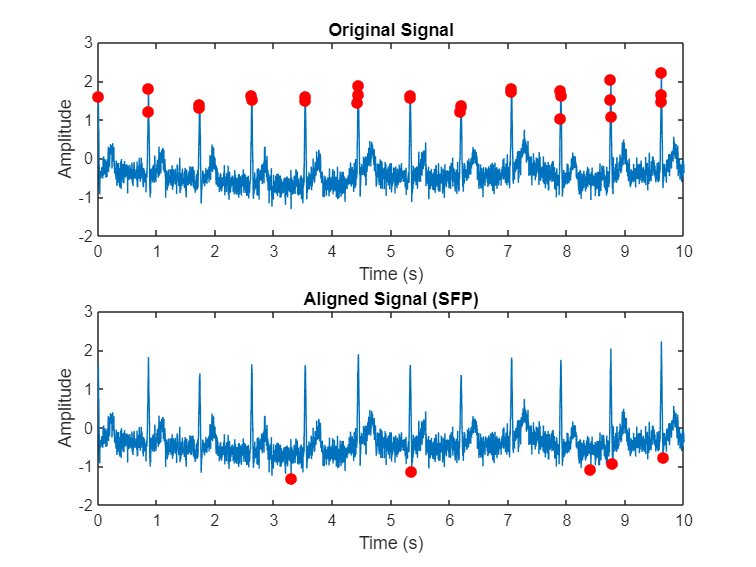

% Beat Alignment - Single Fiducial Point (SFP)  
new_sig = out.simout;


fs = 1500; % sr
lp_c = 3; % low-pass cutoff 
hp_c = 30; % high-pass cutoff

[b, a] = butter(2, [lp_c, hp_c]/(fs/2), 'bandpass');
sfp_wave = filter(b, a, new_sig);

% R-peaks
[~, R_locs] = findpeaks(new_sig, 'MinPeakDistance', 0.3, 'MinPeakHeight', 1);


% Apply SFP
SFP_locs = zeros(size(R_locs));
for i = 1:length(R_locs)
    % Find zero-crossing point after R peak
    [~, loc] = min(new_sig(R_locs(i):end));
    SFP_locs(i) = R_locs(i) + loc - 1;
end


% Plots
% Plot original and aligned signals
t = (1:length(new_sig))/fs; % time axis
% figure;
subplot(2,1,1);
plot(t, new_sig);
hold on;
plot(t(R_locs), new_sig(R_locs), 'ro', 'MarkerFaceColor', 'r');
xlim([0 10]);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(2,1,2);
plot(t, new_sig);
xlim([0 10]);
hold on;
plot(t(SFP_locs), new_sig(SFP_locs), 'ro', 'MarkerFaceColor', 'r');
xlim([0 10]);
title('Aligned Signal (SFP)');
xlabel('Time (s)');
ylabel('Amplitude');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.071168   |  SiftMaxRelativeTolerance
      2      |        3     |     0.018859   |  SiftMaxRelativeTolerance
      3      |        2     |     0.017151   |  SiftMaxRelativeTolerance
      4      |        3     |     0.028052   |  SiftMaxRelativeTolerance
      5      |        1     |     0.076136   |  SiftMaxRelativeTolerance
      6      |        2     |     0.062687   |  SiftMaxRelativeTolerance
      7      |        2     |     0.022479   |  SiftMaxRelativeTolerance
      8      |        3     |        0.179   |  SiftMaxRelativeTolerance
Decomposition stopped because the number of extrema in the residual signal is less than the 'MaxNumExtrema' value.


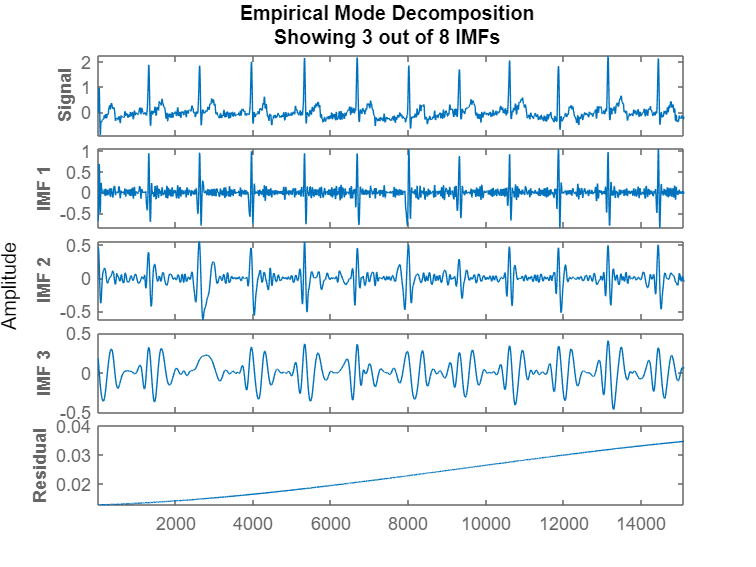

% EMD Implementation
maxiter = 10;
stoppingcriterion = 0.2;
extrapolation = 1;
sig = butter_savit;

emd(sig, "Display", 1);

[imf, res] = emd(butter_savit);

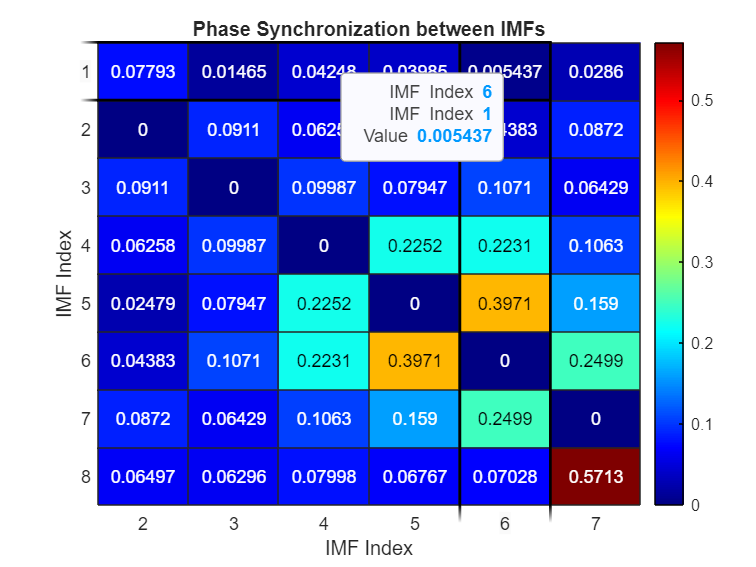

num_imfs = size(imf, 2);

% Initialize matrix to store PSIs
psi_matrix = zeros(num_imfs);

% Loop through all pairs of IMFs
for i = 1:num_imfs
    for j = i+1:num_imfs
        
        % Calculate the Hilbert transform of each IMF
        hilb_i = hilbert(imf(:,i));
        hilb_j = hilbert(imf(:,j));
        
        % Calculate the instantaneous phase of each IMF
        phase_i = angle(hilb_i);
        phase_j = angle(hilb_j);
        
        % Calculate the phase difference between the two IMFs
        phase_diff = phase_i - phase_j;
        
        % Calculate the phase synchronization index (PSI)
        N = length(out.simout);
        psi = abs(sum(exp(1i*phase_diff))/N);
        
        % Store the PSI value in the matrix
        psi_matrix(i,j) = psi;
        psi_matrix(j,i) = psi;
    end
end

% Display the PSI matrix
figure;
heatmap(psi_matrix, 'Colormap', jet, 'ColorbarVisible', 'on');
title('Phase Synchronization between IMFs');
xlabel('IMF Index');
ylabel('IMF Index');

imf_hilbert = zeros(size(imf));
for i = 1:size(imf, 2)
    imf_hilbert(:,i) = hilbert(imf(:,i));
end

t = (1:length(out.simout))/fs;
figure
subplot(size(imf,2)+1,1,1);
plot(t, out.simout)
xlabel('Time (s)');
ylabel('Amp');
xlim([0 10]);
title('Original ECG signal');
for i = 1:size(imf, 2)
    subplot(size(imf,2)+1,1,i+1);
    plot(t, real(imf_hilbert(:,i)), 'b', t, imag(imf_hilbert(:,i)), 'r');
    xlabel('Time (s)');
    ylabel('Amp');
    title(['IMF ' num2str(i) ' with HHT']);
    legend('Re', 'Ima');
    xlim([0 10]);
end

% Raw - EMD
out = load("roopecgdyoeraw.mat");
out = out.out;
max(out.tout);
t = linspace(0,max(out.tout),15100);
plot(t, out.simout)

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.17906   |  SiftMaxRelativeTolerance
      2      |        3     |      0.11706   |  SiftMaxRelativeTolerance
      3      |        2     |     0.059985   |  SiftMaxRelativeTolerance
      4      |        2     |      0.12262   |  SiftMaxRelativeTolerance
      5      |        2     |     0.015962   |  SiftMaxRelativeTolerance
      6      |        2     |     0.027481   |  SiftMaxRelativeTolerance
      7      |        2     |     0.050748   |  SiftMaxRelativeTolerance
      8      |        2     |     0.043804   |  SiftMaxRelativeTolerance
      9      |        2     |   0.00019889   |  SiftMaxRelativeTolerance
Decomposition stopped because the number of extrema in the residual signal is less than the 'MaxNumExtrema' value.


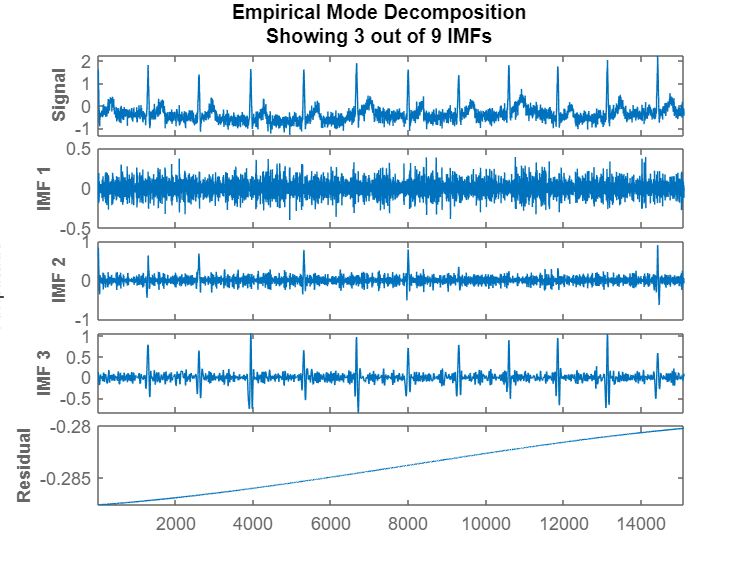

emd(out.simout, "Display",1)

% Implementation of Savitsky Golay Filter on Signal:
out = load("roopecgdyoeraw.mat");
out = out.out;
sig = out.simout;
fs = 1500;
t = (1:length(sig))/fs

t =     0.0007    0.0013    0.0020    0.0027    0.0033    0.0040    0.0047    0.0053    0.0060    0.0067    0.0073    0.0080    0.0087    0.0093    0.0100    0.0107    0.0113    0.0120    0.0127    0.0133    0.0140    0.0147    0.0153    0.0160    0.0167    0.0173    0.0180    0.0187    0.0193    0.0200    0.0207    0.0213    0.0220    0.0227    0.0233    0.0240    0.0247    0.0253    0.0260    0.0267    0.0273    0.0280    0.0287    0.0293    0.0300    0.0307    0.0313    0.0320    0.0327    0.0333


%Hyperparams
window_length = 21;
poly_order = 3;

% Apply the Savitzky-Golay filter to the ECG signal
savit = sgolayfilt(sig, poly_order, window_length);
[~, snr_value] = snr(savit);
snr_value = abs(snr_value)

snr_value = 11.1872


% Butterworth -> Savitsky
butter_savit = sgolayfilt(x_notch, poly_order, window_length)

butter_savit =     0.0198
    0.0005
   -0.0088
   -0.0086
    0.0004
    0.0176
    0.0423
    0.0740
    0.1120
    0.1557


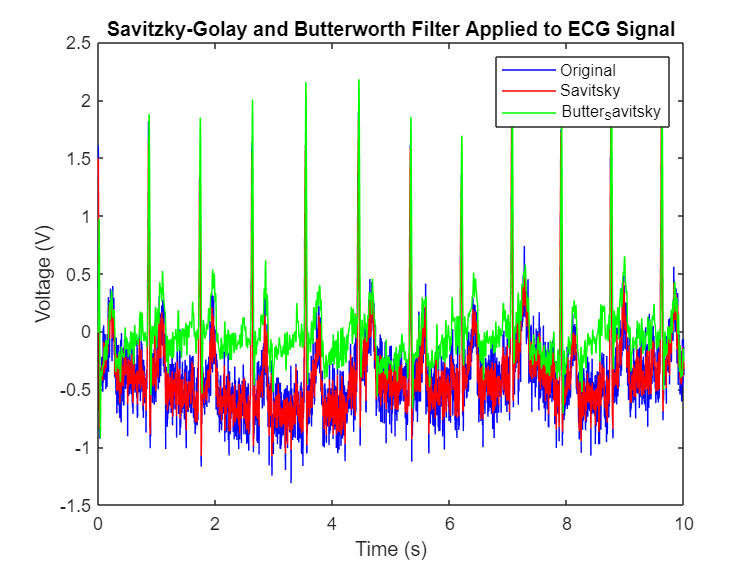


% Plot the original and filtered ECG signals
figure;
plot(t, sig, 'b');
hold on;
plot(t, savit, 'r');
plot(t, butter_savit, 'g');
legend('Original', 'Savitsky', 'Butter_Savitsky');
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Savitzky-Golay and Butterworth Filter Applied to ECG Signal');
xlim([0 10]);

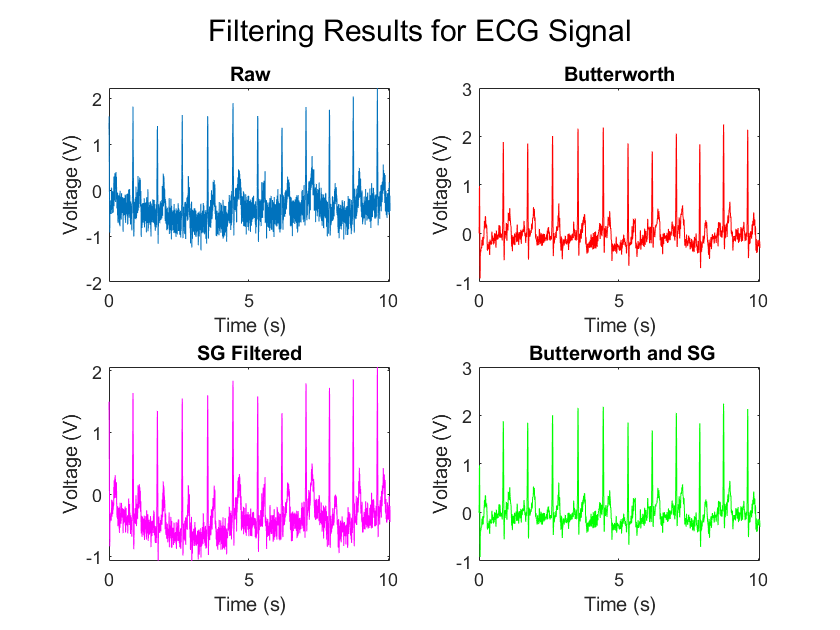



% Plot the raw ECG signal and the filtered signals
figure;

subplot(2, 2, 1);
plot(t, sig);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Raw');

subplot(2, 2, 2);
plot(t, x_notch, 'r');
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Butterworth');

subplot(2, 2, 3);
plot(t, savit, "Color", "magenta");
xlabel('Time (s)');
ylabel('Voltage (V)');
title('SG Filtered');

subplot(2, 2, 4);
plot(t, butter_savit, 'g');
xlabel('Time (s)');
ylabel('Voltage (V)');
title(' Butterworth and SG');

% Adjust the plot layout
sgtitle('Filtering Results for ECG Signal');

[~, snr_val] = snr(butter_savit);
snr_value = abs(snr_val)

snr_value = 10.9177

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.071168   |  SiftMaxRelativeTolerance
      2      |        3     |     0.018859   |  SiftMaxRelativeTolerance
      3      |        2     |     0.017151   |  SiftMaxRelativeTolerance
      4      |        3     |     0.028052   |  SiftMaxRelativeTolerance
      5      |        1     |     0.076136   |  SiftMaxRelativeTolerance
      6      |        2     |     0.062687   |  SiftMaxRelativeTolerance
      7      |        2     |     0.022479   |  SiftMaxRelativeTolerance
      8      |        3     |        0.179   |  SiftMaxRelativeTolerance
Decomposition stopped because the number of extrema in the residual signal is less than the 'MaxNumExtrema' value.


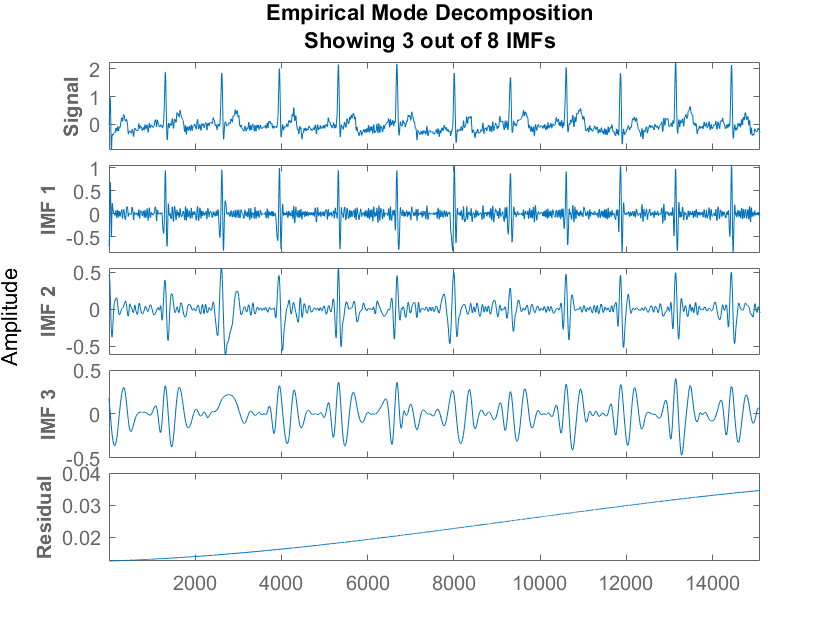

maxiter = 10; % maximum number of iterations
stoppingcriterion = 0.2; % stopping criterion - recommended
extrapolation = 1; % extrapolation method (1 = mirroring, 2 = symmetric)
sig = butter_savit;

emd(sig, "Display", 1)

[imf, res] = emd(sig)

imf =    -0.6789    0.4585    0.1848    0.1286   -0.0700   -0.0275    0.0104    0.0013
   -0.6937    0.4606    0.1787    0.1279   -0.0699   -0.0275    0.0104    0.0013
   -0.6976    0.4619    0.1725    0.1273   -0.0698   -0.0275    0.0104    0.0013
   -0.6912    0.4623    0.1664    0.1266   -0.0696   -0.0275    0.0104    0.0013
   -0.6752    0.4620    0.1602    0.1260   -0.0695   -0.0274    0.0104    0.0013
   -0.6502    0.4608    0.1540    0.1253   -0.0694   -0.0274    0.0104    0.0013
   -0.6167    0.4588    0.1478    0.1247   -0.0693   -0.0274    0.0105    0.0013
   -0.5755    0.4560    0.1416    0.1240   -0.0692   -0.0274    0.0105    0.0013
   -0.5272    0.4525    0.1353    0.1234   -0.0691   -0.0274    0.0105    0.0013
   -0.4723    0.4481    0.1291    0.1227   -0.0690   -0.0274    0.0105    0.0013


res =     0.0127
    0.0127
    0.0127
    0.0127
    0.0127
    0.0127
    0.0127
    0.0127
    0.0127
    0.0127


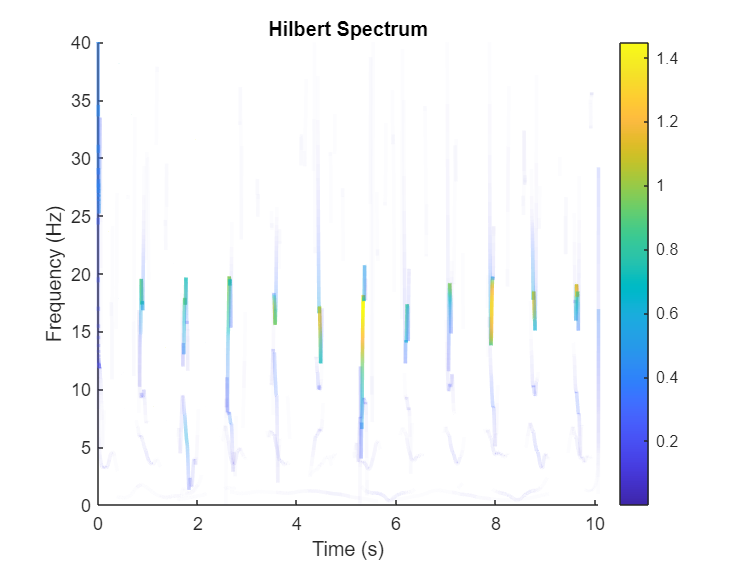

hht(imf,1500)
ylim([0 40])

% Analysis:
sig = butter_savit;

% Define the parameters for the PSD function
windowLength = 1024;
overlap = windowLength/2; % amount of overlap between adjacent windows
samplingFrequency = 1500; % sampling frequency of the ECG signal
f = linspace(0, samplingFrequency/2, windowLength/2+1); % frequency vector for plotting

% Compute the PSD of the ECG signal using the Welch method
[psd, f] = pwelch(sig, windowLength, overlap, [], samplingFrequency);

% Visualize the PSD using a log-log plot
figure;
loglog(f, psd);
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');


windowLength = 512;
overlap = windowLength/2;
samplingFrequency = 1500; 

[S, F, T] = spectrogram(sig, windowLength, overlap, [], samplingFrequency);

% Visualize the spectrogram using a surf plot
figure;
surf(T, F, 10*log10(abs(S)), 'EdgeColor', 'none');
axis tight;
view(0,90);
xlabel('Time (sec)');
ylabel('Frequency (Hz)');

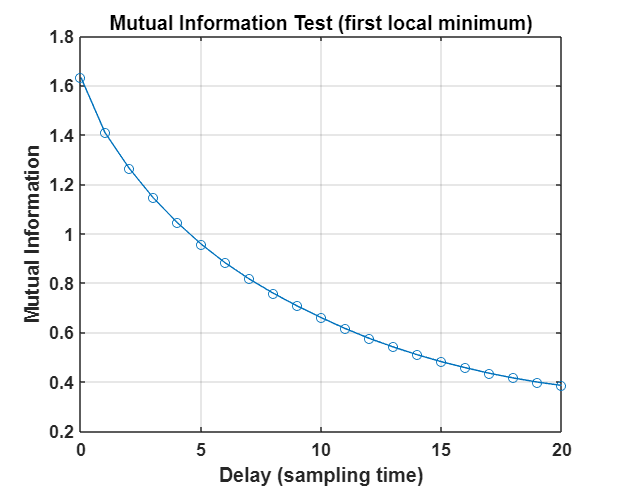

% Recurrence Plot analysis
addpath(genpath('C:\Users\st022\OneDrive\Documents\Spring23\415\contains_all_data\415\RecurrencePlot_ToolBox'));
out = load("roopecgdyoeraw.mat");
out = out.out;
sig = out.simout;

mutual(butter_savit);


% fnn test to determine embedding dimension
out=false_nearest(butter_savit,1,10,8);

Start for dimension=1
Found 15031 up to epsilon=3.161648e-03
Found 15074 up to epsilon=4.471246e-03
Found 15086 up to epsilon=6.323296e-03
Found 15092 up to epsilon=8.942491e-03
Found 15096 up to epsilon=1.264659e-02
Found 15098 up to epsilon=1.788498e-02
Found 15099 up to epsilon=2.529318e-02
Start for dimension=2
Found 11819 up to epsilon=3.161648e-03
Found 12997 up to epsilon=4.471246e-03
Found 13657 up to epsilon=6.323296e-03
Found 13986 up to epsilon=8.942491e-03
Found 14256 up to epsilon=1.264659e-02
Found 14478 up to epsilon=1.788498e-02
Found 14686 up to epsilon=2.529318e-02
Found 14899 up to epsilon=3.576997e-02
Found 14899 up to epsilon=5.058637e-02
Start for dimension=3
Found 1709 up to epsilon=3.161648e-03
Found 3720 up to epsilon=4.471246e-03
Found 7080 up to epsilon=6.323296e-03
Found 10294 up to epsilon=8.942491e-03
Found 12397 up to epsilon=1.264659e-02
Found 13510 up to epsilon=1.788498e-02
Found 14120 up to epsilon=2.529318e-02
Found 14464 up to epsilon=3.576997e-02
F

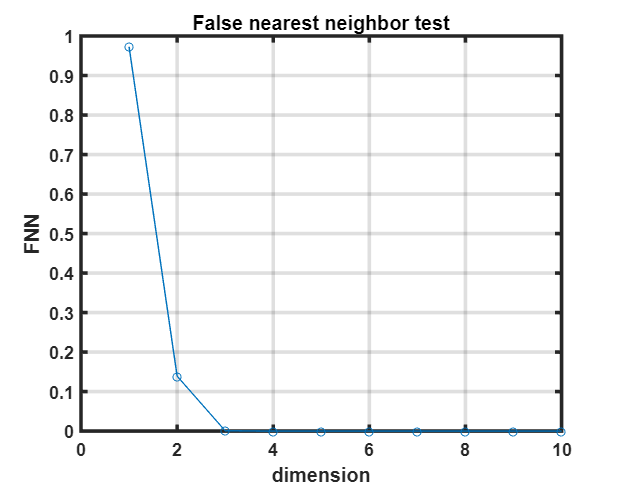

fnn = out(:,1:2);
figure('Position',[100 400 460 360]);
plt=plot(fnn(:,1),fnn(:,2),'o-','MarkerSize',4.5);
title('False nearest neighbor test','FontSize',10,'FontWeight','bold');
xlabel('dimension','FontSize',10,'FontWeight','bold');
ylabel('FNN','FontSize',10,'FontWeight','bold');
get(gcf,'CurrentAxes');
set(gca,'LineWidth',2,'FontSize',10,'FontWeight','bold');
grid on;

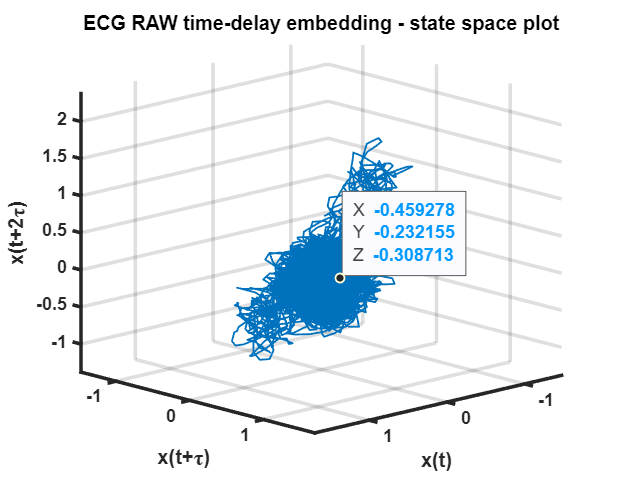

% phase plot
y = phasespace(sig,3,10); % switch to x_notch with sig to see raw


figure('Position',[100 400 460 360]);
plot3(y(:,1),y(:,2),y(:,3),'-','LineWidth',1);
title('ECG RAW time-delay embedding - state space plot','FontSize',10,'FontWeight','bold');
grid on;
set(gca,'CameraPosition',[25.919 27.36 13.854]);
xlabel('x(t)','FontSize',10,'FontWeight','bold');
ylabel('x(t+\tau)','FontSize',10,'FontWeight','bold');
zlabel('x(t+2\tau)','FontSize',10,'FontWeight','bold');
set(gca,'LineWidth',2,'FontSize',10,'FontWeight','bold');



% [1] H. Yang, “Multiscale Recurrence Quantification Analysis of Spatial Vectorcardiogram (VCG)
% Signals,” IEEE Transactions on Biomedical Engineering, Vol. 58, No. 2, p339-347, 2011
% DOI: 10.1109/TBME.2010.2063704
% [2] Y. Chen and H. Yang, "Multiscale recurrence analysis of long-term nonlinear and
% nonstationary time series," Chaos, Solitons and Fractals, Vol. 45, No. 7, p978-987, 2012
% DOI: 10.1016/j.chaos.2012.03.013

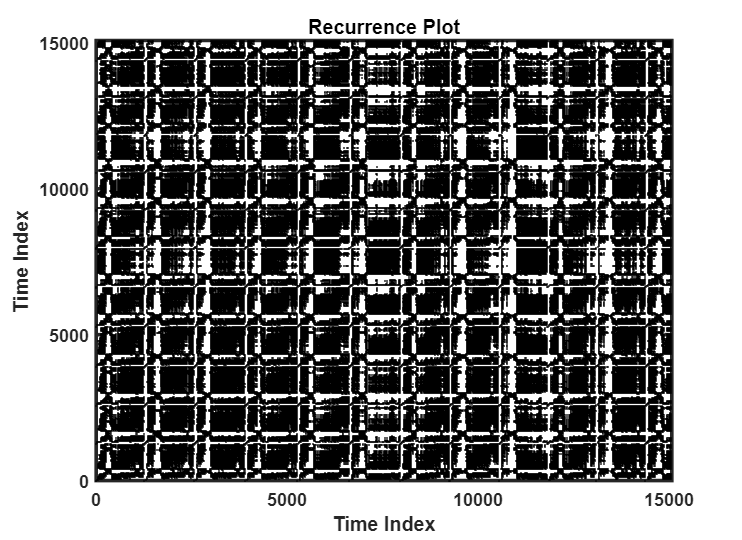

rqa_stat = 1.0e+04 *

    0.0077    0.0100    1.5079    0.0007    0.0100    0.0067


% color recurrence plot
cerecurr_y(y);
recurdata = cerecurr_y(y);